##  Nuñez Peralta Yanet (202132131)

## Tarea 1

### **Ejercicios del libro Universidad Técnica de Loja**

 Problema 11 a): Construir una matriz añadiendo la matriz identidad de rango 3 a la derecha de la matriz A.

A = [1 1 0; 0 2 3; 3 3 1]

A =      1     1     0
     0     2     3
     3     3     1


Aa = [A, eye(3)] 

Aa =      1     1     0     1     0     0
     0     2     3     0     1     0
     3     3     1     0     0     1


Problema 11 b): Sumar a la tercera fila, la primera fila multiplicada por 3.

A(3, :) = A(3, :) + 3 * A(1, :)

A =      1     1     0
     0     2     3
     6     6     1


Problema 11 c): Cambiar la primera columna de A por la tercera.

A(:, 1) = A(:, 3)

A =      0     1     0
     3     2     3
     1     6     1


Problema 11 d): Construir una nueva matriz cuyas columnas sean las columnas primera y tercera de A.

A = [1 1 0; 0 2 3; 3 3 1];
A(:, [1, 3])

ans =      1     0
     0     3
     3     1


Problema 11 e): Construir una nueva matriz cuyas filas sean las columnas primera y tercera de A..    

A([1, 3], :)

ans =      1     1     0
     3     3     1


Problema 12 a): valor minimo dentro de cada fila de A

A = [3 3 7; 0 2 3; 1 4 0]

A =      3     3     7
     0     2     3
     1     4     0


m=min(A,[],2)

m =      3
     0
     0


Problema 12 b): Ordenar los elementos de A en orden descendente dentro de cada columna. 

D=sort(A, 'descend')

D =      3     4     7
     1     3     3
     0     2     0


Problema 12 c): Ordenar los elementos de A en orden ascendente dentro de cada fila. 

C=sort(A, 2, 'ascend')

C =      3     3     7
     0     2     3
     0     1     4


Problema 12 d): Formar una lista con los elementos de A ordenada de forma ascendente.

D=(sort(A(:)))'

D =      0     0     1     2     3     3     3     4     7


Problema 12 e): Hallar el máximo en valor absoluto de los elementos de la matriz A.

M=max(A(:))

M = 7

P013. En una sola orden de MATLAB crear una matriz 3 x 5 cuyo único elemento sea el 7.

U=ones(3, 5) * 7

U =      7     7     7     7     7
     7     7     7     7     7
     7     7     7     7     7


P018. Construir una matriz n x n, C = (Cij)

a. Con Cij = i·j;

n = input('Dar valor de n');
c = zeros(n);
for i = 1:n
    for j = 1:n
        c(i, j) = i * j;
    end
end
disp(c)

     1     2     3     4
     2     4     6     8
     3     6     9    12
     4     8    12    16



b. Con cij = cos(i·j);

n = input('Dar valor de n');
c = zeros(n);
for i = 1:n
    for j = 1:n
        c(i, j) = cos(i * j);
    end
end
disp(c)

    0.5403   -0.4161   -0.9900   -0.6536    0.2837
   -0.4161   -0.6536    0.9602   -0.1455   -0.8391
   -0.9900    0.9602   -0.9111    0.8439   -0.7597
   -0.6536   -0.1455    0.8439   -0.9577    0.4081
    0.2837   -0.8391   -0.7597    0.4081    0.9912



P027. Dados los escalares a = 5, b = 2, c = -4 , determinar los valores de verdad de las proposiciones.

a = 5;
b = 2;
c = -4;

a) ( a < b and a > c) or (b > c)

L1=((a < b) && (a > c)) || (b > c)

L1 = logical
   1


b) ( a ≥ b and b ≤ c) and (a > c)

L2=((a >= b) && (b <= c)) && (a > c)

L2 = logical
   0


c) or (a > b) or (a > c)

L3=(a > b) || (a > c)

L3 = logical
   1


d) or ( a > b) or ((a > c) and (b < a ))

L4=(a > b) || ((a > c) && (b < a))

L4 = logical
   1


e) (  a < b and a > c) or (b > c)

L5=((a < b) && (a > c)) || (b > c)

L5 = logical
   1


P028. Escribir un programa en MATLAB para determinar si un número entero dado es par o impar utilizando el operador `mod` (módulo). 

numero = input('Ingrese un número entero: ');
disp(numero)

     5



if mod(numero, 2) == 0
    disp(' es un número par.');
else
    disp(' es un número impar');
end

 es un número impar


P029. Utilizando el operador relacional > (mayor que), escribir un archivo.m que permita definir si un número a es mayor que un número b. El programa debe admitir ingresar los números a y b, e imprimir el resultado a es mayor que b, o a es menor que b, o a es igual a b.

a = input('Ingrese un numero: ');
b = input('Ingrese otro numero: ');

if a > b
    disp(['El numero ', num2str(a), ' ES MAYOR QUE ', num2str(b)]);
else
    disp(['El numero ', num2str(a), ' ES MENOR QUE ', num2str(b)]);
end

El numero 6 ES MAYOR QUE 5


P030. Escribir un archivo.m que de como resultado el menor de tres números a, b, c. Utilice la sentencia de control if...elseif...end

a = input('Ingrese un numero: ');
b = input('Ingrese otro numero: ');
c= input('Ingrese otro numero: ');

if a <= b && a <= c
        menor = a;
elseif b <= a && b <= c
        menor = b;
else
        menor = c;
end
disp(menor)

     4



P034. Escribir un programa que permita imprimir los números impares del 1 al 100. Utilizar la sentencia while ... end

num = 1;
while num < 100
    disp(num);
    num = num + 2;
end

     1

     3

     5

     7

     9

    11

    13

    15

    17

    19

    21

    23

    25

    27

    29

    31

    33

    35

    37

    39

    41

    43

    45

    47

    49

    51

    53

    55

    57

    59

    61

    63

    65

    67

    69

    71

    73

    75

    77

    79

    81

    83

    85

    87

    89

    91

    93

    95

    97

    99



P036. Crear un archivo.m que de como resultado la suma de los números pares comprendidos entre el 2 y el 100.

rangomin = 2;
suma = 0;
while rangomin<=100
    suma=suma+rangomin;
    rangomin = rangomin+2;
end
disp(suma)

        2550



P038. Implementar un programa que permita evaluar el factorial de un número entero positivo. Por ejemplo

Si n = 5: S = 5*4*3*2*1

Si n = 3: S = 3*2*1

num = input('Ingrese un número natural positivo: ');
f= 1;
desg= (['Factorial de ' num2str(num), ' es: ']);
for i = 1:num
    f = f * i;
    if i == 1
        desg = [desg num2str(i)];
    else
        desg = [desg ' x ' num2str(i)];
    end
end
disp([desg ' = ' num2str(f)]);

Factorial de 7 es: 1 x 2 x 3 x 4 x 5 x 6 x 7 = 5040


P039. Crear archivos.m de función para evaluar la suma total de los n primeros términos dadas las siguientes series:

a. S = 1 + 3 + 5 + 7 + ...

n = input('Ingrese la cantidad de términos a sumar: ');
suma = 0;
for i = 1:n
    termino = 2 * i - 1;
    suma = suma + termino;
end
disp(['La suma de los primeros ', num2str(n), ' términos de la serie es: ', num2str(suma)]);

La suma de los primeros 6 términos de la serie es: 36


b. S = −1/1 +1/2 −1/3 +1/4 − . . .  +1/n

n = input('Ingrese la cantidad de términos a sumar: ');
suma = 0;
for i = 1:n
    termino = (-1)^i / i;  
    suma = suma + termino;  
end
disp(['La suma de los primeros ', num2str(n), ' términos de la serie es: ', num2str(suma)]);

La suma de los primeros 5 términos de la serie es: -0.78333


c. S = 1-2+3-5+8-13+21-34+ . . .

n=input("Ingrese la cantidad de terminos a sumar: ");
a=0;
b=1;
i=0;
for k=1:n
    c=a+b;
    i=i+(-1)^(k+1)*c;
    a=b;
    b=c;
end
disp(['La suma total de los ', num2str(n), ' primeros terminos es: ', num2str(i)]);

La suma total de los 4 primeros terminos es: -3


d. S = 1/1!-1/3!+1/5!-1/7!+ . . . 

n = input('Ingrese el número de términos a sumar: ');
s = 0;
for k=1:n
    s = s +(-1)^(k+1)/factorial(2*k-1);
end
disp(['La suma de los primeros ', num2str(n), ' términos de la serie es: ', num2str(s)]);

La suma de los primeros 7 términos de la serie es: 0.84147


P040. Implementar un programa que permita ingresar n números y ordenarlos de acuerdo a las opciones de mayor a menor.

n = input('Ingrese la cantidad de números: ');
disp('Ingrese los números uno por uno:');

Ingrese los números uno por uno:


numeros = zeros(1, n);
for i = 1:n
    numeros(i) = input('Ingrese un número: ');
end

for i = 1:n-1
    for j = 1:n-i
        if numeros(j) < numeros(j+1)
            temp = numeros(j);
            numeros(j) = numeros(j+1);
            numeros(j+1) = temp;
        end
    end
end

disp('Los numeros ordenados de mayor a menor son: ')

Los numeros ordenados de mayor a menor son: 


disp(numeros);

     7     6     6     5     4     4     3     2



P044. Crear un archivo.m que permita evaluar las series. Los argumentos de entrada son x y n, donde n es el número de términos que se evalúan en la serie y x es un número real:

a) Serie A .


$$S=x-\frac{x^2 }{2}+\frac{x^3 }{3}-\ldotp \ldotp \ldotp \ldotp$$


x = input('Ingrese el valor de x ');
n = input('Ingrese el valor de n ');
suma = 0;
for i=1:n
    if mod(i, 2) == 0
        suma = suma - ((x^i)/i);
    else
        suma = suma + ((x^i)/i);
    end
end

disp(['La suma de los premeros ', num2str(n), 'dado ', num2str(x), 'es: ',num2str(suma)])

La suma de los premeros 5dado 4es: 158.1333


b) Serie B.  $S=\frac{1}{2}x-\frac{1*3}{2*4}x^3 +\frac{1*3*5}{2*4*6}x^5 -\frac{1*3*5*7}{2*4*6*8}x^7 +\ldotp \ldotp \ldotp$

x = input('Ingrese el valor de x ');
n = input('Ingrese el valor de n ');
i= 0;
for k=1:n
    s=(-1)^(k+1)*x^(2*k-1)*(prod(2*k-1:-2:1)/prod(2*k:-2:1));
    i=i+s;
end
disp(['La suma de los premeros ', num2str(n), 'dado ', num2str(x), 'es: ',num2str(i)])

La suma de los premeros 5dado 4es: 60330


c) Serie C.  


$$S=x-\frac{1}{2}\frac{x^1 }{{\left(1+x\right)}^1 }+\frac{\left(1-3\right)}{2*4}\frac{x^2 }{{\left(1+x\right)}^3 }-\frac{\left(1-3+5\right)}{2*4*6}\frac{\;x^3 }{{\left(1+x\right)}^5 }+\;\ldotp \;\ldotp \;\ldotp$$


x = input('Ingrese el valor de x ');
n = input('Ingrese el valor de n ');
i= 0;
for k=1:n
    s=(-1)^(k+1)*x^(k-1)/(1+x)^(2*k-1)*(((-1)^(k+1)*(2*k-1))/prod(2*k:-2:1));
    i=i+s;
end
disp(['La suma de los premeros ', num2str(n), ' numeros dado ', num2str(x), ' es: ',num2str(i)])

La suma de los premeros 7 numeros dado 4 es: 0.11255


P052. Imprimir los múltiplos de 7 existentes entre dos valores m y n pedido al usuario. Modificar el algoritmo para que calcule cuántos números hay y su suma.

m = input('Ingrese el valor de m: ');
n = input('Ingrese el valor de n: ');

contador_multiplos = 0;
suma_multiplos = 0;

for numero = m:n
    if rem(numero, 7) == 0 
        disp(['Es múltiplo ', num2str(numero)]);
        contador_multiplos = contador_multiplos + 1; 
        suma_multiplos = suma_multiplos + numero; 
    end
end

disp(['Total de múltiplos de 7: ', num2str(contador_multiplos)]);

Total de múltiplos de 7: 0


disp(['Suma de los múltiplos de 7:', num2str(suma_multiplos)]);

Suma de los múltiplos de 7:0


P053. Imprimir los n primeros términos de la serie de Fibonacci. Los términos de dicha serie se calculan de la siguiente forma: a0=1; a1=1; ai= ai-1+ai-2, i=2,...n.

n = input('Ingrese el número de términos de la serie de Fibonacci que desea imprimir: ');
a = zeros(1, n);
a(1) = 1;
a(2) = 1;
for i = 3:n
    a(i) = a(i-1) + a(i-2);
end
disp(['Los primeros ' num2str(n) 'términos de la serie de Fibonacci son:', n]);

Los primeros 4términos de la serie de Fibonacci son:□


for i = 1:n
    disp(a(i));
end

     1

     1

     2

     3



P055. Imprimir todos los números primos que hay entre dos pedidos al usuario.

m = input('Ingrese el valor de m: ');
n = input('Ingrese el valor de n: ');

disp(['Números primos en el rango de ', num2str(m), ' a ', num2str(n)]);

Números primos en el rango de 5 a 6



for numero = m:n
    es_primo = true;    
    if numero <= 1
        es_primo = false;
    else
        for divisor = 2:sqrt(numero)
            if rem(numero, divisor) == 0
                es_primo = false;
                break;
            end
        end
    end
    
    if es_primo
        disp(numero);
    end
end

     5



P067. Use los comandos de MATLAB para graficar las siguientes funciones, en el dominio especificado:

a. f(x)= 5-4x-x^2, [6, -2]    

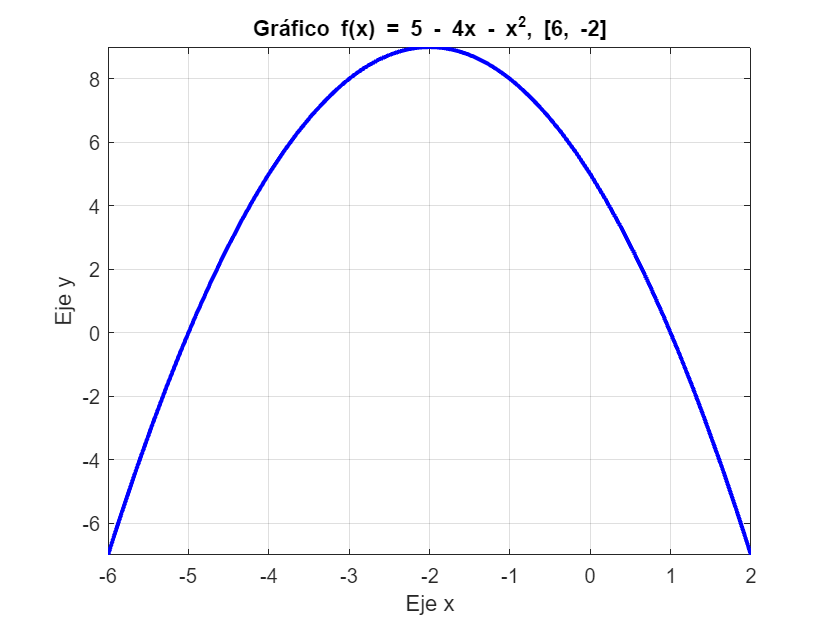

f = @(x) 5 - 4*x - x.^2;
fplot(f, [-6, 2],'b', 'LineWidth',2);
title('Gráfico f(x) = 5 - 4x - x^2, [6, -2]');
xlabel('Eje x');
ylabel('Eje y');
grid on;

b.  f(x) = 2x^2 - 8x -11, [-1,5]

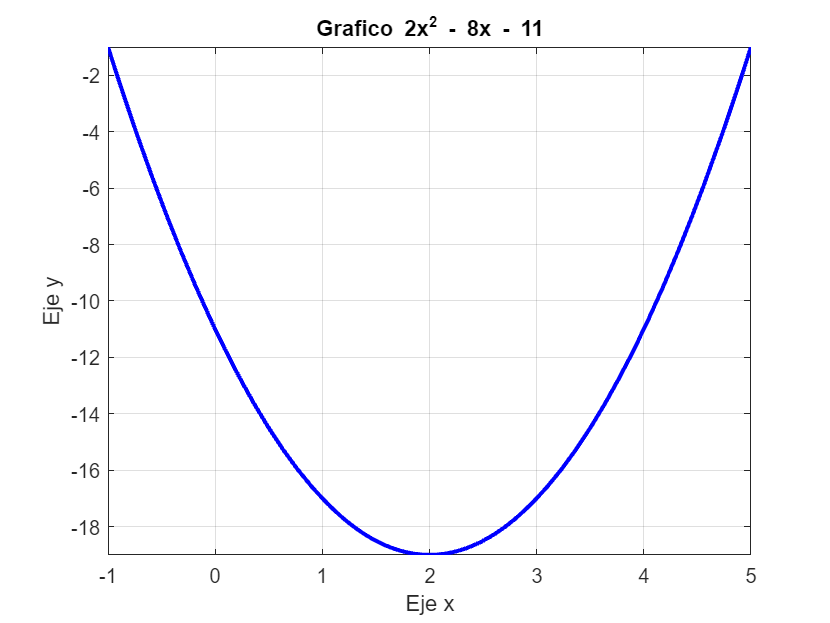

f = @(x) 2*x.^2 - 8*x - 11;
fplot(f, [-1, 5],'b', 'LineWidth',2);
title("Grafico 2x^2 - 8x - 11");
xlabel('Eje x');
ylabel('Eje y');
grid on;

c .f(t) =  t*e^(-2*t), [-1, 5]

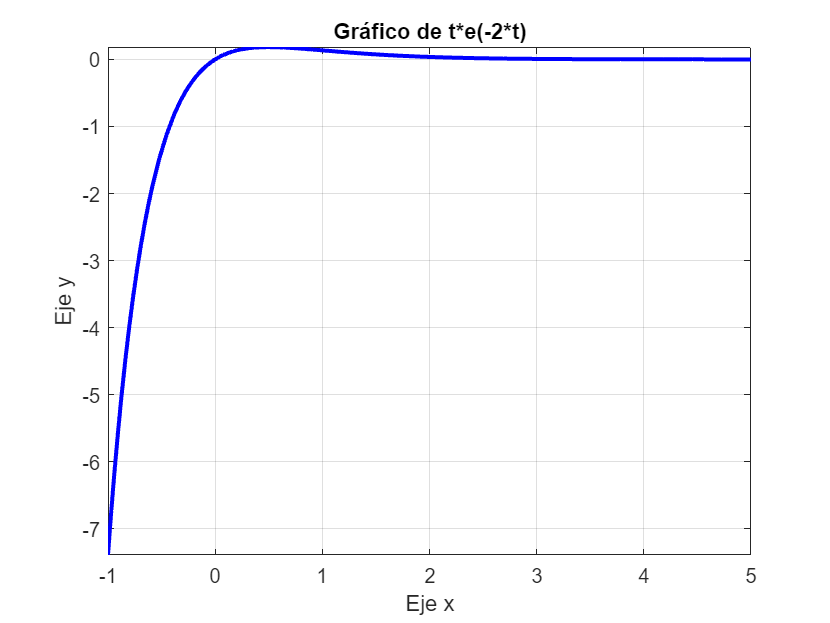

f = @(t) t.* exp(-2 * t);
fplot(f, [-1, 5],'b', 'LineWidth',2);
title("Gráfico de t*e(-2*t)");
xlabel('Eje x');
ylabel('Eje y');
grid on;

d. =  h(t) =  e ^(-0.1t sin(2t)), [0, 4pi]

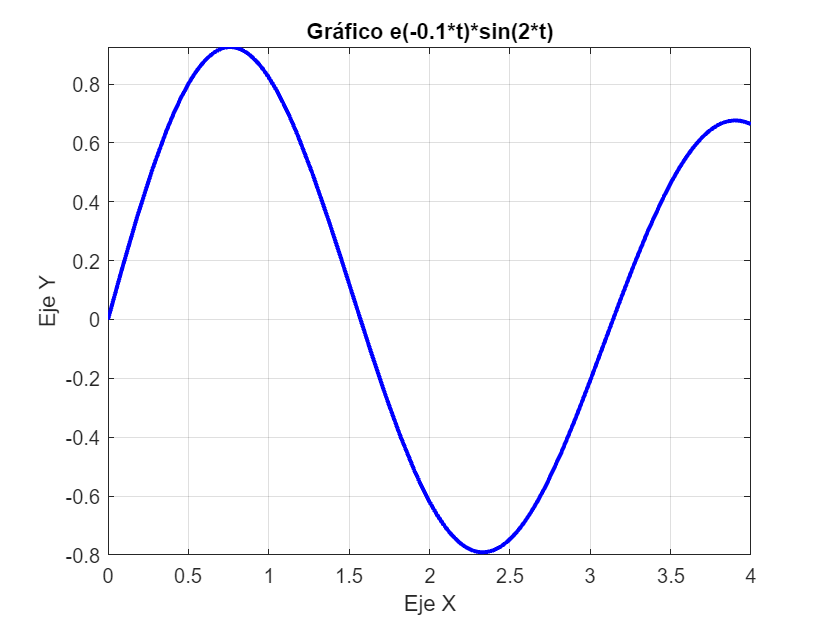

t=@(t)exp(-0.1*t).*sin(2*t);
fplot(t,[0, 4],'b', 'LineWidth',2);
title('Gráfico e(-0.1*t)*sin(2*t)');
xlabel('Eje X');
ylabel('Eje Y');
grid on;

P071. Representar la superficie cuya función explícita es la siguiente:

a)

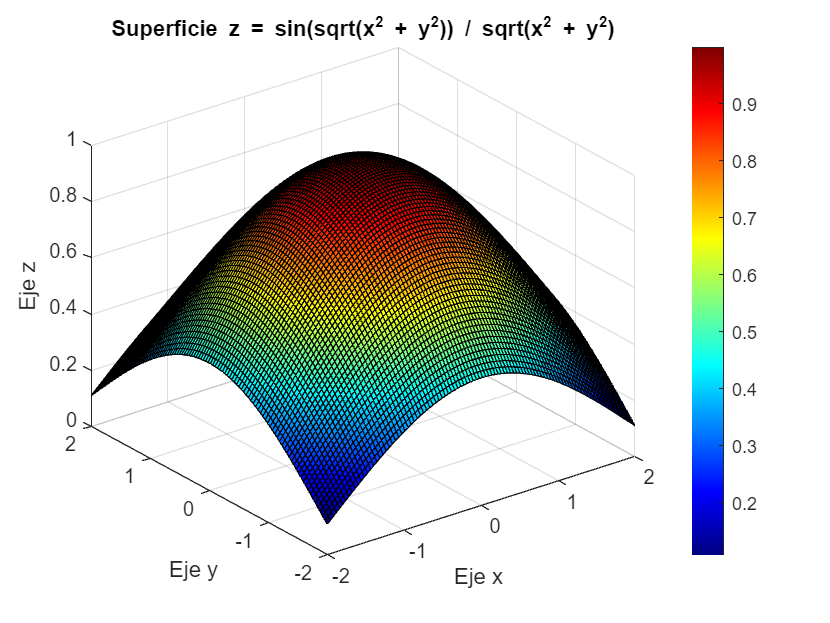

z = @(x, y) sin(sqrt(x.^2 + y.^2)) ./ sqrt(x.^2 + y.^2);
[x, y] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
z_values = z(x, y);
surf(x, y, z_values);
title('Superficie z = sin(sqrt(x^2 + y^2)) / sqrt(x^2 + y^2)');
xlabel('Eje x');
ylabel('Eje y');
zlabel('Eje z');
colormap('cool'); 
colorbar; 

b)

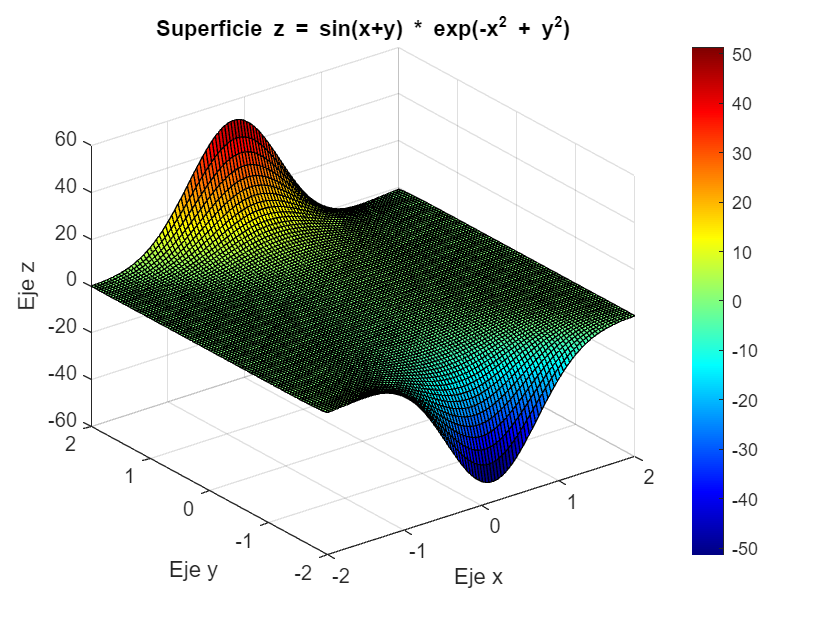

z = @(x, y) sin(x + y) .* exp(-x.^2 + y.^2);
[x, y] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
z_values = z(x, y);
surf(x, y, z_values);
title('Superficie z = sin(x+y) * exp(-x^2 + y^2)');
xlabel('Eje x');
ylabel('Eje y');
zlabel('Eje z');
colormap('cool');
colorbar;

c)

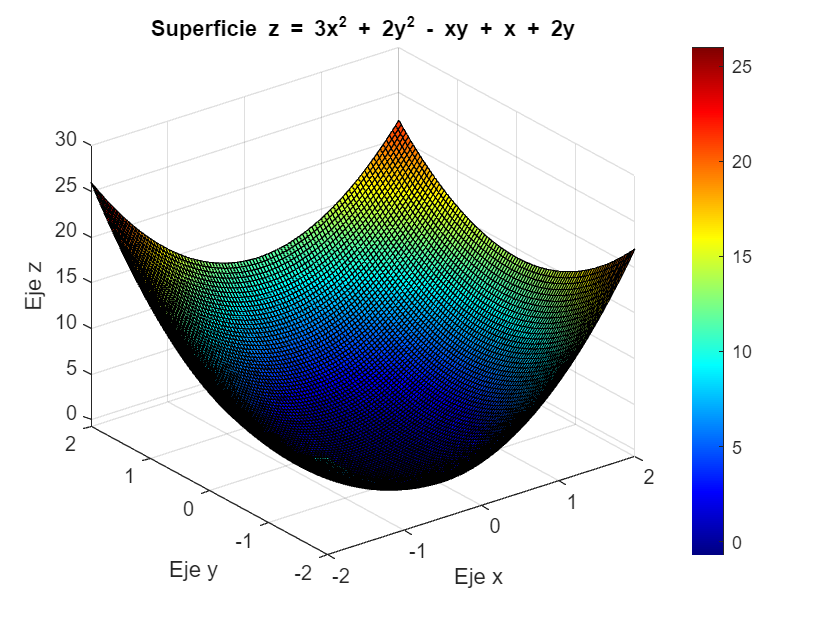

z = @(x, y) 3*x.^2 + 2*y.^2 - x.*y + x + 2*y;
[x, y] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
z_values = z(x, y);
surf(x, y, z_values);
title('Superficie z = 3x^2 + 2y^2 - xy + x + 2y');
xlabel('Eje x');
ylabel('Eje y');
zlabel('Eje z');
colormap('cool');
colorbar; 

d)

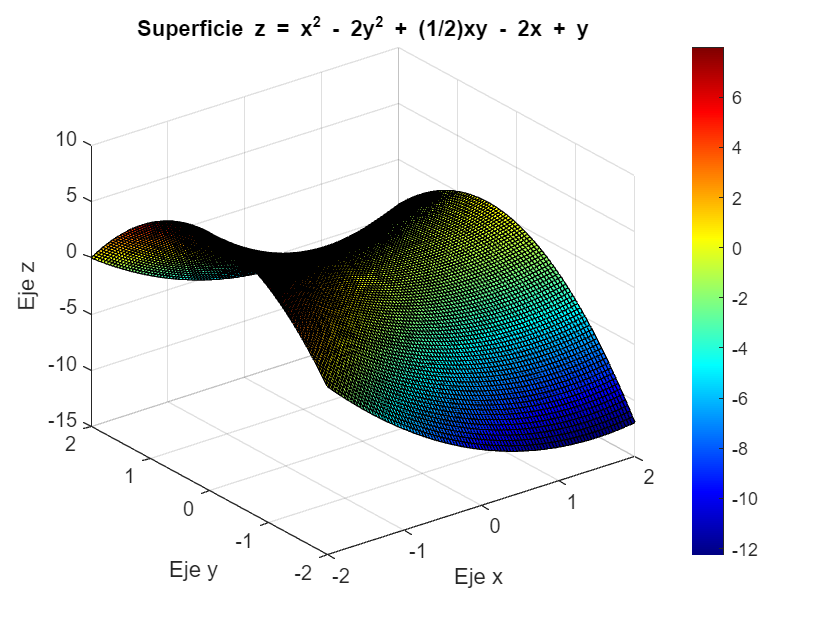

z = @(x, y) x.^2 - 2*y.^2 + (1/2)*x.*y - 2*x + y;
[x, y] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
z_values = z(x, y);
surf(x, y, z_values);
title('Superficie z = x^2 - 2y^2 + (1/2)xy - 2x + y');
xlabel('Eje x');
ylabel('Eje y');
zlabel('Eje z');
colormap('cool'); 
colorbar; 